clear all
clear

fileName = 'DHPC.xlsx'; % Replace with your file name


dataArray = readmatrix(fileName, 'Sheet','Folha2');


chunk_size = dataArray(1, 4:36);

serial = dataArray(23:26, 4);

%Dynamic

Manldelbrot_dynamic = dataArray(2, 4:36);
Julia_dynamic = dataArray(3, 4:36);
Tricorn_dynamic = dataArray(4, 4:36);
Cosine_dynamic = dataArray(5, 4:36);

Manldelbrot_speedup_dynamic = serial(1,1)./Manldelbrot_dynamic;
Julia_speedup_dynamic = serial(2,1)./Julia_dynamic;
Tricorn_speedup_dynamic = serial(3,1)./Tricorn_dynamic;
Cosine_speedup_dynamic = serial(4,1)./Cosine_dynamic;

%Guided

Manldelbrot_guided = dataArray(9, 4:36);
Julia_guided = dataArray(10, 4:36);
Tricorn_guided = dataArray(11, 4:36);
Cosine_guided = dataArray(12, 4:36);

Manldelbrot_speedup_guided = serial(1,1)./Manldelbrot_guided;
Julia_speedup_guided = serial(2,1)./Julia_guided;
Tricorn_speedup_guided = serial(3,1)./Tricorn_guided;
Cosine_speedup_guided = serial(4,1)./Cosine_guided;

%Static

Manldelbrot_static = dataArray(16, 4:36);
Julia_static = dataArray(17, 4:36);
Tricorn_static = dataArray(18, 4:36);
Cosine_static = dataArray(19, 4:36);

Manldelbrot_speedup_static = serial(1,1)./Manldelbrot_static;
Julia_speedup_static = serial(2,1)./Julia_static;
Tricorn_speedup_static = serial(3,1)./Tricorn_static;
Cosine_speedup_static = serial(4,1)./Cosine_static;

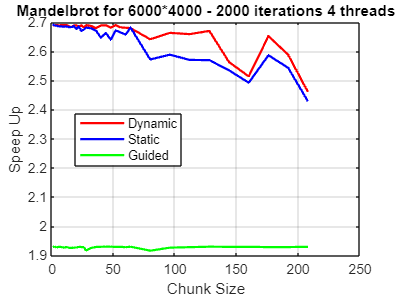

%Plot Mandlebrot

% Data for plotting
x = chunk_size; % X-axis values
y1 = Manldelbrot_speedup_dynamic;           
y2 = Manldelbrot_speedup_static;              
y3 = Manldelbrot_speedup_guided;           


% Create the plot
figure;                   % Open a new figure window
plot(x, y1, '-r', 'LineWidth', 1.5); hold on; % Line 1: Red
plot(x, y2, '-b', 'LineWidth', 1.5);          % Line 2: Blue
plot(x, y3, '-g', 'LineWidth', 1.5);          % Line 3: Green


% Add labels and title
xlabel('Chunk Size');         % X-axis label
ylabel('Speep Up');         % Y-axis label
title('Mandelbrot for 6000*4000 - 2000 iterations 4 threads');  % Title of the plot

% Add legend
legend('Dynamic', 'Static', 'Guided', 'Location', 'best');

% Display grid
grid on;

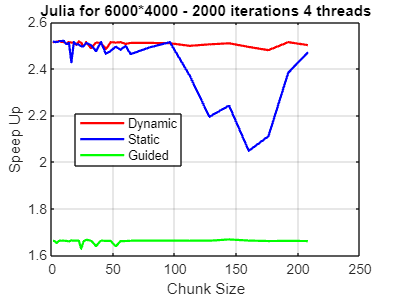

%Plot Julia

% Data for plotting
x = chunk_size; % X-axis values
y1 = Julia_speedup_dynamic;           
y2 = Julia_speedup_static;              
y3 = Julia_speedup_guided;           


% Create the plot
figure;                   % Open a new figure window
plot(x, y1, '-r', 'LineWidth', 1.5); hold on; % Line 1: Red
plot(x, y2, '-b', 'LineWidth', 1.5);          % Line 2: Blue
plot(x, y3, '-g', 'LineWidth', 1.5);          % Line 3: Green


% Add labels and title
xlabel('Chunk Size');         % X-axis label
ylabel('Speep Up');         % Y-axis label
title('Julia for 6000*4000 - 2000 iterations 4 threads');  % Title of the plot

% Add legend
legend('Dynamic', 'Static', 'Guided', 'Location', 'best');

% Display grid
grid on;

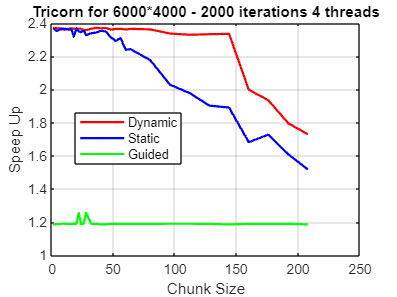

%Plot Tricorn

% Data for plotting
x = chunk_size; % X-axis values
y1 = Tricorn_speedup_dynamic;           
y2 = Tricorn_speedup_static;              
y3 = Tricorn_speedup_guided;           


% Create the plot
figure;                   % Open a new figure window
plot(x, y1, '-r', 'LineWidth', 1.5); hold on; % Line 1: Red
plot(x, y2, '-b', 'LineWidth', 1.5);          % Line 2: Blue
plot(x, y3, '-g', 'LineWidth', 1.5);          % Line 3: Green


% Add labels and title
xlabel('Chunk Size');         % X-axis label
ylabel('Speep Up');         % Y-axis label
title('Tricorn for 6000*4000 - 2000 iterations 4 threads');  % Title of the plot

% Add legend
legend('Dynamic', 'Static', 'Guided', 'Location', 'best');

% Display grid
grid on;

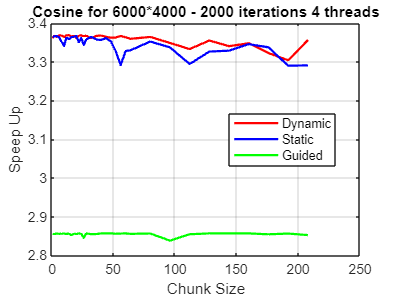

%Plot Cosine

% Data for plotting
x = chunk_size; % X-axis values
y1 = Cosine_speedup_dynamic;           
y2 = Cosine_speedup_static;              
y3 = Cosine_speedup_guided;           


% Create the plot
figure;                   % Open a new figure window
plot(x, y1, '-r', 'LineWidth', 1.5); hold on; % Line 1: Red
plot(x, y2, '-b', 'LineWidth', 1.5);          % Line 2: Blue
plot(x, y3, '-g', 'LineWidth', 1.5);          % Line 3: Green


% Add labels and title
xlabel('Chunk Size');         % X-axis label
ylabel('Speep Up');         % Y-axis label
title('Cosine for 6000*4000 - 2000 iterations 4 threads');  % Title of the plot

% Add legend
legend('Dynamic', 'Static', 'Guided', 'Location', 'best');

% Display grid
grid on;

ntreads_server = dataArray(33, 4:37);

Manldelbrot_server = dataArray(34, 4:37);
Julia_server = dataArray(35, 4:37);
Tricorn_server = dataArray(36, 4:37);
Cosine_server = dataArray(37, 4:37);

Manldelbrot_speedup_server = serial(1,1)./Manldelbrot_server;
Julia_speedup_server = serial(2,1)./Julia_server;
Tricorn_speedup_server = serial(3,1)./Tricorn_server;
Cosine_speedup_server = serial(4,1)./Cosine_server;

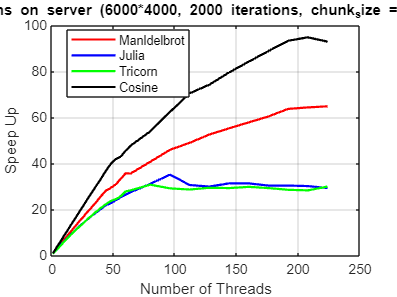

%Plot speed up

% Data for plotting
x = ntreads_server; % X-axis values
y1 = Manldelbrot_speedup_server;           
y2 = Julia_speedup_server;              
y3 = Tricorn_speedup_server;
y4 = Cosine_speedup_server;


% Create the plot
figure;                   % Open a new figure window
plot(x, y1, '-r', 'LineWidth', 1.5); hold on; % Line 1: Red
plot(x, y2, '-b', 'LineWidth', 1.5);          % Line 2: Blue
plot(x, y3, '-g', 'LineWidth', 1.5);          % Line 3: Green
plot(x, y4, 'k', 'LineWidth', 1.5);         

% Add labels and title
xlabel('Number of Threads');         % X-axis label
ylabel('Speep Up');         % Y-axis label

title('Speed up for all graphs on server (6000*4000, 2000 iterations, chunk_size = 6, schedule = dynamic)')

% Add legend
legend('Manldelbrot', 'Julia', 'Tricorn', 'Cosine', 'Location', 'best');

% Display grid
grid on;

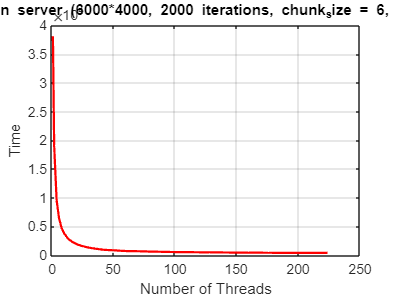

%Plot Mandelbrot

% Data for plotting
x = ntreads_server; % X-axis values
y1 = Manldelbrot_server;           

% Create the plot
figure;                   % Open a new figure window
plot(x, y1, '-r', 'LineWidth', 1.5); hold on; % Line 1: Red

% Add labels and title
xlabel('Number of Threads');         % X-axis label 
ylabel('Time');         % Y-axis label
title('Mandelbrot Time on server (6000*4000, 2000 iterations, chunk_size = 6, schedule = dynamic)')

% Display grid
grid on;

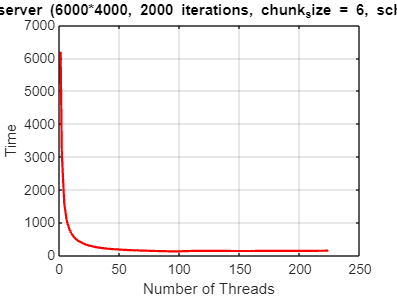

%Plot Julia

% Data for plotting
x = ntreads_server; % X-axis values
y1 = Julia_server;           

% Create the plot
figure;                   % Open a new figure window
plot(x, y1, '-r', 'LineWidth', 1.5); hold on; % Line 1: Red

% Add labels and title
xlabel('Number of Threads');         % X-axis label
ylabel('Time');         % Y-axis label
title('Julia Time on server (6000*4000, 2000 iterations, chunk_size = 6, schedule = dynamic)')

% Display grid
grid on;

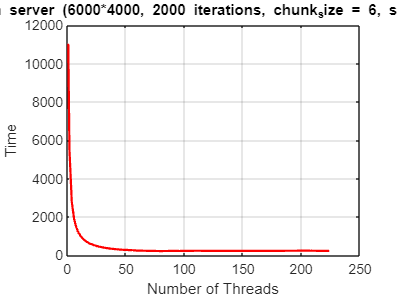

% Data for plotting
x = ntreads_server; % X-axis values
y1 = Tricorn_server;           

% Main plot
figure;                   % Open a new figure window
plot(x, y1, '-r', 'LineWidth', 1.5); hold on; % Line 1: Red

% Add labels and title
xlabel('Number of Threads');         % X-axis label
ylabel('Time');         % Y-axis label
title('Tricorn Time on server (6000*4000, 2000 iterations, chunk_size = 6, schedule = dynamic)')

grid on;

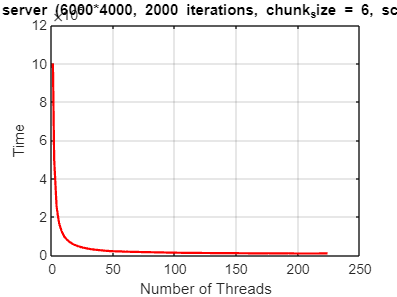

%Plot Cosine

% Data for plotting
x = ntreads_server; % X-axis values
y1 = Cosine_server;           

% Main plot
figure;                   % Open a new figure window
plot(x, y1, '-r', 'LineWidth', 1.5); hold on; % Line 1: Red

% Add labels and title
xlabel('Number of Threads');         % X-axis label
ylabel('Time');         % Y-axis label
title('Cosine Time on server (6000*4000, 2000 iterations, chunk_size = 6, schedule = dynamic)')

% Display grid on the main plot
grid on;